# Lab5

# MirHamed Jafarzadeh - 810195374

# Sajjad Pakdaman Savoji - 810195517

## *Part 5 - 1: Initialization of Parameters ("dcl_init.m" Loading)*

clear
close all
clc
dcl_init

## *Part 5 - 2: Modulation Transmitter Implementation*

**1.  Bit Generating**

b_tx = bit_gen(pkt_size, k)

b_tx =      1     1
     1     1
     0     1
     1     0
     1     1
     0     0
     0     1
     1     1
     1     0
     1     1


**2. Bit-to-Symbol Mapping**

b_gray = gray_code(k)

b_gray =      0     0
     0     1
     1     1
     1     0


sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end
sym_idx

sym_idx =      3     3     2     4     3     1     2     3     4     3     2     4     3     1     4     2     2     3     4     4     4     2     4     4     4     3     4     2     4     2     4     1     2     1     1     3     3     1     3     1     1     1     4     4     1     2     2     3     4     4


[psk_cons, Es_avg] = constellation(M,'psk');
mod_sym = psk_cons(sym_idx)

mod_sym =   -1.0000 + 0.0000i  -1.0000 + 0.0000i   0.0000 + 1.0000i  -0.0000 - 1.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i  -0.0000 - 1.0000i  -1.0000 + 0.0000i   0.0000 + 1.0000i  -0.0000 - 1.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -0.0000 - 1.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i  -0.0000 - 1.0000i  -0.0000 - 1.0000i  -0.0000 - 1.0000i   0.0000 + 1.0000i  -0.0000 - 1.0000i  -0.0000 - 1.0000i  -0.0000 - 1.0000i  -1.0000 + 0.0000i  -0.0000 - 1.0000i   0.0000 + 1.0000i  -0.0000 - 1.0000i   0.0000 + 1.0000i  -0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i  -1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i   1.0000 + 0.0000i  -0.0000 - 1.0000i  -0.0000 - 1.0000i   1.0000 + 0.0000i   0.0000 + 1.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i  -0.0000 - 1.0000i  -0.0000 - 1.0000i


**3. Transmitting Pulse Shaping**

[tx_smpl, cnstl] = pulse_modulation(sym_idx, 'psk', M, fs, smpl_per_symbl, 'triangular', 'conv')

tx_smpl =    0.0000 + 0.0000i  -0.1508 + 0.0000i  -0.3015 + 0.0000i  -0.4523 + 0.0000i  -0.6030 + 0.0000i  -0.4523 + 0.0000i  -0.3015 + 0.0000i  -0.1508 + 0.0000i   0.0000 + 0.0000i  -0.1508 + 0.0000i  -0.3015 + 0.0000i  -0.4523 + 0.0000i  -0.6030 + 0.0000i  -0.4523 + 0.0000i  -0.3015 + 0.0000i  -0.1508 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.1508i   0.0000 + 0.3015i   0.0000 + 0.4523i   0.0000 + 0.6030i   0.0000 + 0.4523i   0.0000 + 0.3015i   0.0000 + 0.1508i   0.0000 + 0.0000i  -0.0000 - 0.1508i  -0.0000 - 0.3015i  -0.0000 - 0.4523i  -0.0000 - 0.6030i  -0.0000 - 0.4523i  -0.0000 - 0.3015i  -0.0000 - 0.1508i   0.0000 + 0.0000i  -0.1508 + 0.0000i  -0.3015 + 0.0000i  -0.4523 + 0.0000i  -0.6030 + 0.0000i  -0.4523 + 0.0000i  -0.3015 + 0.0000i  -0.1508 + 0.0000i   0.0000 + 0.0000i   0.1508 + 0.0000i   0.3015 + 0.0000i   0.4523 + 0.0000i   0.6030 + 0.0000i   0.4523 + 0.0000i   0.3015 + 0.0000i   0.1508 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.1508i


cnstl =    1.0000 + 0.0000i   0.0000 + 1.0000i  -1.0000 + 0.0000i  -0.0000 - 1.0000i


## *Part 5 - 3: Channel Modeling*

**1.  Adding Delay to Channel**

delay = zeros(1, chnl_delay_in_smpl);
tx_smpl_delayed = [delay tx_smpl];

**2.  Adding Phase Offset to Channel**

rx_smpl = tx_smpl_delayed.*exp(1i * chnl_phase_offset);

**3.  Channel Simulation With White Gaussian Noise**

**        3.1. Compute Noise Characteristics**

Eb = Es_avg / log2(M);
EbNo = db2pow(10);
var_noise = 0.5*(Eb/EbNo);

**        3.2. Adding Noise to Signal**

n_real = randn(1, length(rx_smpl)) * sqrt(var_noise);
n_imag = randn(1, length(rx_smpl)) * sqrt(var_noise);
noise_smpl = n_real + 1i*n_imag;
rx_smpl_noise = rx_smpl + noise_smpl;

## *Part 5 - 4: Modulation Reciever Implementation*

**1.  Pulse Demodulation**

rx_smpl = rx_smpl_noise(chnl_delay_in_smpl+1:end);
[det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, 'psk', M, fs, smpl_per_symbl, 'triangular', 'correlator');

**2.  Gray-to-Binary Convertion**

det_bit = b_gray(det_sym_idx, :);

**3.  SER computation**

ser = 1 - sum(det_sym_idx == sym_idx)/length(sym_idx)

ser = 6.0000e-06

**4.  BER computation**

ber = 1 - sum(sum(det_bit == b_tx))/size(det_bit, 1)/size(det_bit, 2)

ber = 3.0000e-06

## *Part 5 - 5: General Claims*

**1.  SER and BER Computations and Plots of ****Simulation**** vs ****MATLAB****:**

**    i. 4-PAM**

M = 4;
k = log2(M);

b_tx = bit_gen(pkt_size, k);
b_gray = gray_code(k)

b_gray =      0     0
     0     1
     1     1
     1     0


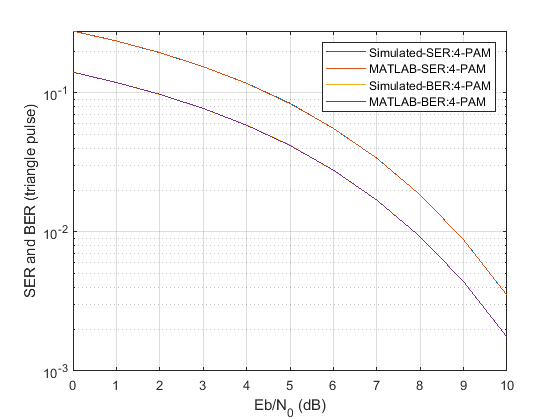

sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end
[cons, Es_avg] = constellation(M,'pam');
mod_sym = cons(sym_idx);

[tx_smpl_tri, cnstl_tri] = pulse_modulation(sym_idx, 'pam', M, fs, smpl_per_symbl, 'triangular', 'conv');
span_in_symbl = 1;
[tx_smpl_rrc, cnstl_rrc] = pulse_modulation(sym_idx, 'pam', M, fs, smpl_per_symbl, 'root_raised_cosine', 'conv', [beta span_in_symbl]);

delay = zeros(1, chnl_delay_in_smpl);
tx_smpl_delayed_tri = [delay tx_smpl_tri];
tx_smpl_delayed_rrc = [delay tx_smpl_rrc];
rx_smpl_tri = tx_smpl_delayed_tri.*exp(1i * chnl_phase_offset);
rx_smpl_rrc = tx_smpl_delayed_rrc.*exp(1i * chnl_phase_offset);

SNR = (snr_min:snr_step:snr_max)';
Eb_pam = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_pam./EbNo);

ser_pam_tri = zeros(length(var_noise), 1);
ser_pam_rrc = zeros(length(var_noise), 1);
ber_pam_tri = zeros(length(var_noise), 1);
ber_pam_rrc = zeros(length(var_noise), 1);

for i = 1:length(var_noise)
    n_real = randn(1, length(rx_smpl_tri)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_tri)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_tri = rx_smpl_tri + noise_smpl;
    
    n_real = randn(1, length(rx_smpl_rrc)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_rrc)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_rrc = rx_smpl_rrc + noise_smpl;
    
    rx_smpl_out_tri = rx_smpl_noise_tri(chnl_delay_in_smpl+1:end);
    rx_smpl_out_rrc = rx_smpl_noise_rrc(chnl_delay_in_smpl+1:end);
    
    [det_sym_idx_tri, rx_sym_tri] = pulse_demodulation(rx_smpl_out_tri, 'pam', M, fs, smpl_per_symbl, 'triangular', 'correlator');
    [det_sym_idx_rrc, rx_sym_rrc] = pulse_demodulation(rx_smpl_out_rrc, 'pam', M, fs, smpl_per_symbl, 'root_raised_cosine', 'correlator', [beta span_in_symbl]);
     
    det_bit_tri = b_gray(det_sym_idx_tri, :);
    det_bit_rrc = b_gray(det_sym_idx_rrc, :);
    
    ser_pam_tri(i) = 1 - sum(det_sym_idx_tri == sym_idx)/length(sym_idx);
    ser_pam_rrc(i) = 1 - sum(det_sym_idx_rrc == sym_idx)/length(sym_idx);
    
    ber_pam_tri(i) = 1 - sum(sum(det_bit_tri == b_tx))/size(det_bit_tri, 1)/size(det_bit_tri, 2);
    ber_pam_rrc(i) = 1 - sum(sum(det_bit_rrc == b_tx))/size(det_bit_rrc, 1)/size(det_bit_rrc, 2);
end

[ber_mat_pam, ser_mat_pam] = berawgn(SNR, 'pam', M);

semilogy(SNR, [ser_pam_tri ser_mat_pam ber_pam_tri ber_mat_pam])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER (triangle pulse)')
legend('Simulated-SER:4-PAM','MATLAB-SER:4-PAM','Simulated-BER:4-PAM','MATLAB-BER:4-PAM')
grid

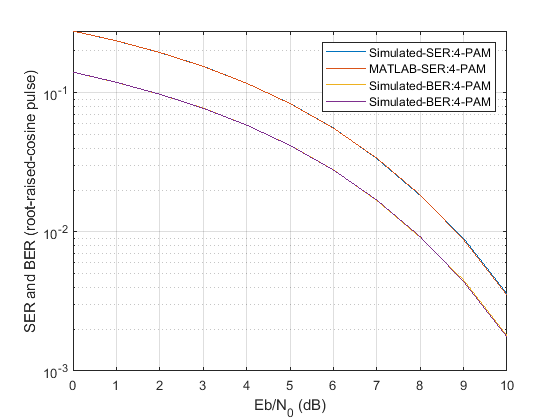


semilogy(SNR, [ser_pam_rrc ser_mat_pam ber_pam_rrc ber_mat_pam])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER (root-raised-cosine pulse)')
legend('Simulated-SER:4-PAM','MATLAB-SER:4-PAM','Simulated-BER:4-PAM','Simulated-BER:4-PAM')
grid

**    ii. 8-PSK**

M = 8;
k = log2(M);

b_tx = bit_gen(pkt_size, k);
b_gray = gray_code(k)

b_gray =      0     0     0
     0     0     1
     0     1     1
     0     1     0
     1     1     0
     1     1     1
     1     0     1
     1     0     0


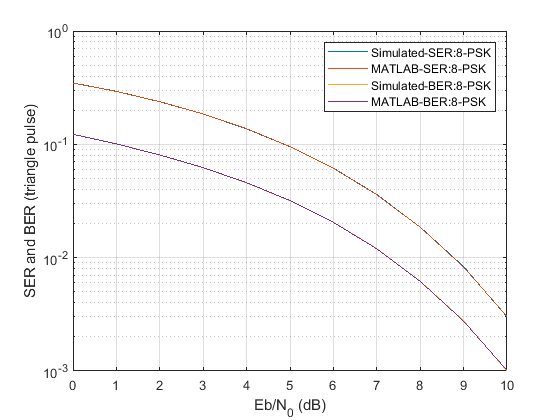

sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end
[cons, Es_avg] = constellation(M,'psk');
mod_sym = cons(sym_idx);

[tx_smpl_tri, cnstl_tri] = pulse_modulation(sym_idx, 'psk', M, fs, smpl_per_symbl, 'triangular', 'conv');
span_in_symbl = 1;
[tx_smpl_rrc, cnstl_rrc] = pulse_modulation(sym_idx, 'psk', M, fs, smpl_per_symbl, 'root_raised_cosine', 'conv', [beta span_in_symbl]);

delay = zeros(1, chnl_delay_in_smpl);
tx_smpl_delayed_tri = [delay tx_smpl_tri];
tx_smpl_delayed_rrc = [delay tx_smpl_rrc];
rx_smpl_tri = tx_smpl_delayed_tri.*exp(1i * chnl_phase_offset);
rx_smpl_rrc = tx_smpl_delayed_rrc.*exp(1i * chnl_phase_offset);

SNR = (snr_min:snr_step:snr_max)';
Eb_psk = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_psk./EbNo);

ser_psk_tri = zeros(length(var_noise), 1);
ser_psk_rrc = zeros(length(var_noise), 1);
ber_psk_tri = zeros(length(var_noise), 1);
ber_psk_rrc = zeros(length(var_noise), 1);

for i = 1:length(var_noise)
    n_real = randn(1, length(rx_smpl_tri)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_tri)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_tri = rx_smpl_tri + noise_smpl;
    
    n_real = randn(1, length(rx_smpl_rrc)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_rrc)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_rrc = rx_smpl_rrc + noise_smpl;
    
    rx_smpl_out_tri = rx_smpl_noise_tri(chnl_delay_in_smpl+1:end);
    rx_smpl_out_rrc = rx_smpl_noise_rrc(chnl_delay_in_smpl+1:end);
    
    [det_sym_idx_tri, rx_sym_tri] = pulse_demodulation(rx_smpl_out_tri, 'psk', M, fs, smpl_per_symbl, 'triangular', 'correlator');
    [det_sym_idx_rrc, rx_sym_rrc] = pulse_demodulation(rx_smpl_out_rrc, 'psk', M, fs, smpl_per_symbl, 'root_raised_cosine', 'correlator', [beta span_in_symbl]);
     
    det_bit_tri = b_gray(det_sym_idx_tri, :);
    det_bit_rrc = b_gray(det_sym_idx_rrc, :);
    
    ser_psk_tri(i) = 1 - sum(det_sym_idx_tri == sym_idx)/length(sym_idx);
    ser_psk_rrc(i) = 1 - sum(det_sym_idx_rrc == sym_idx)/length(sym_idx);
    
    ber_psk_tri(i) = 1 - sum(sum(det_bit_tri == b_tx))/size(det_bit_tri, 1)/size(det_bit_tri, 2);
    ber_psk_rrc(i) = 1 - sum(sum(det_bit_rrc == b_tx))/size(det_bit_rrc, 1)/size(det_bit_rrc, 2);
end

[ber_mat_psk, ser_mat_psk] = berawgn(SNR, 'psk', M, 'nondiff');

semilogy(SNR, [ser_psk_tri ser_mat_psk ber_psk_tri ber_mat_psk])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER (triangle pulse)')
legend('Simulated-SER:8-PSK','MATLAB-SER:8-PSK','Simulated-BER:8-PSK','MATLAB-BER:8-PSK')
grid

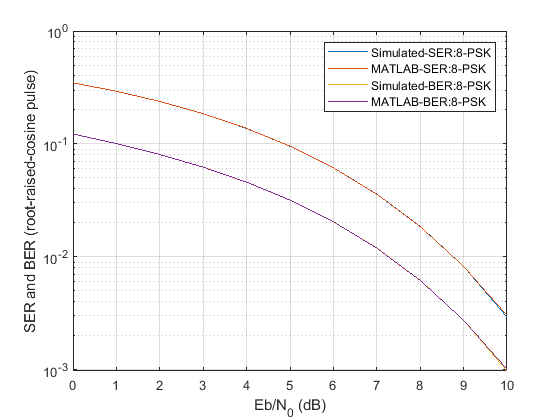


semilogy(SNR, [ser_psk_rrc ser_mat_psk ber_psk_rrc ber_mat_psk])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER (root-raised-cosine pulse)')
legend('Simulated-SER:8-PSK','MATLAB-SER:8-PSK','Simulated-BER:8-PSK','MATLAB-BER:8-PSK')
grid

**    iii.16-QAM**

M = 16;
k = log2(M);

b_tx = bit_gen(pkt_size, k);
b_gray = gray_code(k)

b_gray =      0     0     0     0
     0     0     0     1
     0     0     1     1
     0     0     1     0
     0     1     1     0
     0     1     1     1
     0     1     0     1
     0     1     0     0
     1     1     0     0
     1     1     0     1


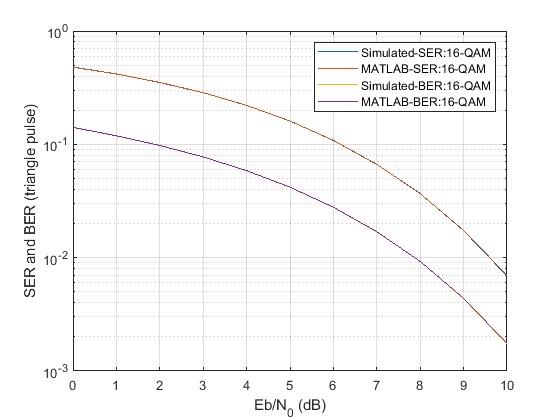

sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end
[cons, Es_avg] = constellation(M,'qam');
mod_sym = cons(sym_idx);

[tx_smpl_tri, cnstl_tri] = pulse_modulation(sym_idx, 'qam', M, fs, smpl_per_symbl, 'triangular', 'conv');
span_in_symbl = 1;
[tx_smpl_rrc, cnstl_rrc] = pulse_modulation(sym_idx, 'qam', M, fs, smpl_per_symbl, 'root_raised_cosine', 'conv', [beta span_in_symbl]);

delay = zeros(1, chnl_delay_in_smpl);
tx_smpl_delayed_tri = [delay tx_smpl_tri];
tx_smpl_delayed_rrc = [delay tx_smpl_rrc];
rx_smpl_tri = tx_smpl_delayed_tri.*exp(1i * chnl_phase_offset);
rx_smpl_rrc = tx_smpl_delayed_rrc.*exp(1i * chnl_phase_offset);

SNR = (snr_min:snr_step:snr_max)';
Eb_qam = Es_avg / log2(M);
EbNo = db2pow(SNR);
var_noise = 0.5*(Eb_qam./EbNo);

ser_qam_tri = zeros(length(var_noise), 1);
ser_qam_rrc = zeros(length(var_noise), 1);
ber_qam_tri = zeros(length(var_noise), 1);
ber_qam_rrc = zeros(length(var_noise), 1);

for i = 1:length(var_noise)
    n_real = randn(1, length(rx_smpl_tri)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_tri)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_tri = rx_smpl_tri + noise_smpl;
    
    n_real = randn(1, length(rx_smpl_rrc)) * sqrt(var_noise(i));
    n_imag = randn(1, length(rx_smpl_rrc)) * sqrt(var_noise(i));
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise_rrc = rx_smpl_rrc + noise_smpl;
    
    rx_smpl_out_tri = rx_smpl_noise_tri(chnl_delay_in_smpl+1:end);
    rx_smpl_out_rrc = rx_smpl_noise_rrc(chnl_delay_in_smpl+1:end);
    
    [det_sym_idx_tri, rx_sym_tri] = pulse_demodulation(rx_smpl_out_tri, 'qam', M, fs, smpl_per_symbl, 'triangular', 'correlator');
    [det_sym_idx_rrc, rx_sym_rrc] = pulse_demodulation(rx_smpl_out_rrc, 'qam', M, fs, smpl_per_symbl, 'root_raised_cosine', 'correlator', [beta span_in_symbl]);
     
    det_bit_tri = b_gray(det_sym_idx_tri, :);
    det_bit_rrc = b_gray(det_sym_idx_rrc, :);
    
    ser_qam_tri(i) = 1 - sum(det_sym_idx_tri == sym_idx)/length(sym_idx);
    ser_qam_rrc(i) = 1 - sum(det_sym_idx_rrc == sym_idx)/length(sym_idx);
    
    ber_qam_tri(i) = 1 - sum(sum(det_bit_tri == b_tx))/size(det_bit_tri, 1)/size(det_bit_tri, 2);
    ber_qam_rrc(i) = 1 - sum(sum(det_bit_rrc == b_tx))/size(det_bit_rrc, 1)/size(det_bit_rrc, 2);
end

[ber_mat_qam, ser_mat_qam] = berawgn(SNR, 'qam', M);

semilogy(SNR, [ser_qam_tri ser_mat_qam ber_qam_tri ber_mat_qam])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER (triangle pulse)')
legend('Simulated-SER:16-QAM','MATLAB-SER:16-QAM','Simulated-BER:16-QAM','MATLAB-BER:16-QAM')
grid

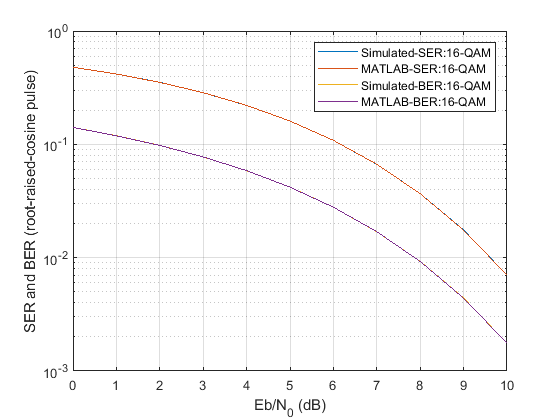


semilogy(SNR, [ser_qam_rrc ser_mat_qam ber_qam_rrc ber_mat_qam])
xlabel('Eb/N_0 (dB)')
ylabel('SER and BER (root-raised-cosine pulse)')
legend('Simulated-SER:16-QAM','MATLAB-SER:16-QAM','Simulated-BER:16-QAM','MATLAB-BER:16-QAM')
grid

**    iv. BER Plot for 4-PAM, 8-PSK and 16-QAM**

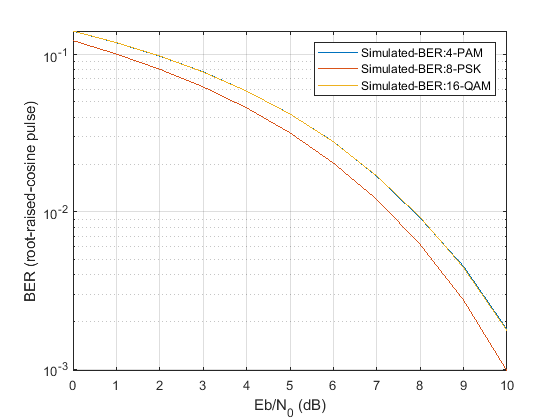

semilogy(SNR, [ber_pam_rrc ber_psk_rrc ber_qam_rrc])
xlabel('Eb/N_0 (dB)')
ylabel('BER (root-raised-cosine pulse)')
legend('Simulated-BER:4-PAM','Simulated-BER:8-PSK','Simulated-BER:16-QAM')
grid

**2.  Delay Effect on Channel**

**        2.1 Effect of Delay on BER and Constellation**

**        *** **It should be said that constellation is constant and does not depend on channel effects.

delay_coefs = [0.1, 0.5, 0.8];
modulation = 'psk';
M = 4;
k = log2(M);
pulse_name = 'triangular';
EbNo = db2pow(10);

b_tx = bit_gen(pkt_size, k);

b_gray = gray_code(k);
sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end
[psk_cons, Es_avg] = constellation(M, modulation);
mod_sym = psk_cons(sym_idx);

[tx_smpl, cnstl] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'kron');

for i=1:length(delay_coefs)
    chnl_delay_in_smpl = round(delay_coefs(i)*smpl_per_symbl);
    % make delay
    delay = zeros(1, chnl_delay_in_smpl);
    tx_smpl_delayed = [delay tx_smpl];
    % phase shift
    rx_smpl = tx_smpl_delayed.*exp(1i * chnl_phase_offset);
    % noise specifications
    Eb = Es_avg / log2(M);
    var_noise = 0.5*(Eb/EbNo);
    % add noise
    n_real = randn(1, length(rx_smpl)) * sqrt(var_noise);
    n_imag = randn(1, length(rx_smpl)) * sqrt(var_noise);
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise = rx_smpl + noise_smpl;
    % demuodulation
    rx_smpl = rx_smpl_noise(1:end - chnl_delay_in_smpl);
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name, 'matched_filter');
    det_bit = b_gray(det_sym_idx, :);
    
    ser_with_delay = 1 - sum(det_sym_idx == sym_idx)/length(sym_idx)
    ber_with_delay = 1 - sum(sum(det_bit == b_tx))/size(det_bit, 1)/size(det_bit, 2)
end

ser_with_delay = 5.5000e-05

ber_with_day = 2.7500e-05

ser_with_delay = 0.4534

ber_with_day = 0.2609

ser_with_delay = 0.7494

ber_with_day = 0.4995


% we have ser and ber of 4-psk without delay from part 5-4
ser

ser = 6.0000e-06

ber

ber = 3.0000e-06

*It is obvious that delay has a very bad effect on SER and BER*

**        2.2.  Adding Header**

hder_bit = repmat(de2bi(hex2dec('1C6387FF5DA4FA325C895958DC5'))', 1, k);

b_tx = bit_gen(pkt_size, k);
% add header------------------------------------
b_tx = cat(1, hder_bit, b_tx);
% ----------------------------------------------

b_gray = gray_code(k);
sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end
[psk_cons, Es_avg] = constellation(M, modulation);
mod_sym = psk_cons(sym_idx);

[tx_smpl, cnstl] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'kron');

% pick time samples of header ----------------
hder_smpl = tx_smpl(1:size(hder_bit, 1)*smpl_per_symbl);
% ------------------------------

**        2.3.  Estimation of Packet Beginning and Compensation of Delay Effect**

for i=1:length(delay_coefs)
    chnl_delay_in_smpl = round(delay_coefs(i)*smpl_per_symbl);
    % make delay
    delay = zeros(1, chnl_delay_in_smpl);
    tx_smpl_delayed = [delay tx_smpl];
    % phase shift
    rx_smpl = tx_smpl_delayed.*exp(1i * chnl_phase_offset);
    % noise specifications
    Eb = Es_avg / log2(M);
    var_noise = 0.5*(Eb/EbNo);
    % add noise
    n_real = randn(1, length(rx_smpl)) * sqrt(var_noise);
    n_imag = randn(1, length(rx_smpl)) * sqrt(var_noise);
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise = rx_smpl + noise_smpl;
    % demuodulation
    % find start of data ------------------------------
    hder_start = find_header(rx_smpl_noise, hder_smpl);
    rx_smpl = rx_smpl_noise(hder_start:end);
    % -------------------------------------------------
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name, 'matched_filter');
    det_bit = b_gray(det_sym_idx, :);
    
    ser_with_delay_hdr = 1 - sum(det_sym_idx == sym_idx)/length(sym_idx)
    ber_with_delay_hdr = 1 - sum(sum(det_bit == b_tx))/size(det_bit, 1)/size(det_bit, 2)
end

ser_with_delay_hdr = 6.9993e-06

ber_with_delay_hdr = 3.4996e-06

ser_with_delay_hdr = 4.9995e-06

ber_with_delay_hdr = 2.4997e-06

ser_with_delay_hdr = 2.9997e-06

ber_with_delay_hdr = 1.4998e-06


% we have ser and ber of 4-psk without delay from part 5-4
ser

ser = 6.0000e-06

ber

ber = 3.0000e-06

*It is obvious that we compensated the delay effect on SER and BER, using the header. (for ber which is lower than the actual ber without delay, we must say that the reason is because of different noises we used in these simulations.)*

**3.  Adding Phase to Channel and Phase Estimation**

**        3.1 Effect of Additional Phase on BER**

**        *** **It should be said that constellation is constant and does not depend on channel effects.

modulation = 'psk';
M = 4;
k = log2(M);
pulse_name = 'triangular';
EbNo = db2pow(10);
chnl_delay_in_smpl = 0;
phase_coefs = [0, 30];

b_tx = bit_gen(pkt_size, k);

b_gray = gray_code(k);
sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end
[psk_cons, Es_avg] = constellation(M, modulation);
mod_sym = psk_cons(sym_idx);

[tx_smpl, cnstl] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'kron');

for i=1:length(phase_coefs)
    %change phase shift value
    chnl_phase_offset = phase_coefs(i)*pi/180;
    % make delay
    delay = zeros(1, chnl_delay_in_smpl);
    tx_smpl_delayed = [delay tx_smpl];
    % phase shift
    rx_smpl = tx_smpl_delayed.*exp(1i * chnl_phase_offset);
    % noise specifications
    Eb = Es_avg / log2(M);
    var_noise = 0.5*(Eb/EbNo);
    % add noise
    n_real = randn(1, length(rx_smpl)) * sqrt(var_noise);
    n_imag = randn(1, length(rx_smpl)) * sqrt(var_noise);
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise = rx_smpl + noise_smpl;
    % demuodulation (delay is zero)
    rx_smpl = rx_smpl_noise(1:end - chnl_delay_in_smpl);
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name, 'matched_filter');
    det_bit = b_gray(det_sym_idx, :);
    
    ser_phase_offset = 1 - sum(det_sym_idx == sym_idx)/length(sym_idx)
    ber_phase_offset = 1 - sum(sum(det_bit == b_tx))/size(det_bit, 1)/size(det_bit, 2)
end

ser_phase_offset = 5.0000e-06

ber_phase_offset = 2.5000e-06

ser_phase_offset = 0.0509

ber_phase_offset = 0.0255

*The first ser and ber, are for the case ****without phase offset**** and the seconds, are for ****30 degrees phase offset****. It is obvious that delay has a very bad effect on SER and BER. It is because phase offset has real and imaginary parts, so the signals change in both coordinates.*

**        3.2.  Additional Phase Estimation**

hder_bit = repmat(de2bi(hex2dec('1C6387FF5DA4FA325C895958DC5'))', 1, k);

b_tx = bit_gen(pkt_size, k);
% add header------------------------------------
b_tx = cat(1, hder_bit, b_tx);
% ----------------------------------------------

b_gray = gray_code(k);
sym_idx = zeros(1,pkt_size);
for i=1:M
    indx = b_tx(:,1) == b_gray(i,1);
    for j=2:k
        indx = indx & b_tx(:,j) == b_gray(i,j);
    end
    sym_idx(indx) = i;
end
[psk_cons, Es_avg] = constellation(M, modulation);
mod_sym = psk_cons(sym_idx);

[tx_smpl, cnstl] = pulse_modulation(sym_idx, modulation, M, fs, smpl_per_symbl, pulse_name, 'kron');

% pick time samples of header ----------------
hder_smpl = tx_smpl(1:size(hder_bit, 1)*smpl_per_symbl);
% ------------------------------

for i=1:length(phase_coefs)
    %change phase shift value
    chnl_phase_offset = phase_coefs(i)*pi/180;
    % make delay
    delay = zeros(1, chnl_delay_in_smpl);
    tx_smpl_delayed = [delay tx_smpl];
    % phase shift
    rx_smpl = tx_smpl_delayed.*exp(1i * chnl_phase_offset);
    % noise specifications
    Eb = Es_avg / log2(M);
    var_noise = 0.5*(Eb/EbNo);
    % add noise
    n_real = randn(1, length(rx_smpl)) * sqrt(var_noise);
    n_imag = randn(1, length(rx_smpl)) * sqrt(var_noise);
    noise_smpl = n_real + 1i*n_imag;
    rx_smpl_noise = rx_smpl + noise_smpl;
    % demuodulation
    % phase compensation ------------------------------
    [ph, last_hdr_indx] = find_phase(rx_smpl_noise, hder_smpl);
    rx_smpl = rx_smpl_noise(1:end - chnl_delay_in_smpl);
    rx_smpl = rx_smpl .*exp(-1i * ph);
    % ----------------------------------------------
    [det_sym_idx, rx_sym] = pulse_demodulation(rx_smpl, modulation, M, fs, smpl_per_symbl, pulse_name, 'matched_filter');
    det_bit = b_gray(det_sym_idx, :);
    
    ser_phase_offset_comp = 1 - sum(det_sym_idx == sym_idx)/length(sym_idx)
    ber_phase_offset_comp = 1 - sum(sum(det_bit == b_tx))/size(det_bit, 1)/size(det_bit, 2)
end

ser_phase_offset_comp = 9.9990e-06

ber_phase_offset_comp = 4.9995e-06

ser_phase_offset_comp = 5.9994e-06

ber_phase_offset_comp = 2.9997e-06

*The first ser and ber, are for the case ****without phase offset**** and the seconds, are for ****30 degrees phase offset****. It is obvious that we compensated the phase offset effect on SER and BER, using the header. (for ber which is lower than the actual ber without phase offset, we must say that the reason is because of different noises we used in these simulations.)*

** 3.2.  Channel Phase Compensation**

kernel = fliplr(hder_smpl);
hder_auto_corr = conv(kernel, hder_smpl)

hder_auto_corr = 	1.0e+02 *

   0.0000 + 0.0000i  -0.0002 + 0.0000i  -0.0009 + 0.0000i  -0.0023 + 0.0000i  -0.0045 + 0.0000i  -0.0070 + 0.0000i  -0.0091 + 0.0000i  -0.0100 + 0.0000i  -0.0091 + 0.0000i  -0.0075 + 0.0000i  -0.0064 + 0.0000i  -0.0068 + 0.0000i  -0.0100 + 0.0000i  -0.0143 + 0.0000i  -0.0182 + 0.0000i  -0.0200 + 0.0000i  -0.0182 + 0.0000i  -0.0148 + 0.0000i  -0.0118 + 0.0000i  -0.0114 + 0.0000i  -0.0155 + 0.0000i  -0.0216 + 0.0000i  -0.0273 + 0.0000i  -0.0300 + 0.0000i  -0.0273 + 0.0000i  -0.0216 + 0.0000i  -0.0155 + 0.0000i  -0.0114 + 0.0000i  -0.0118 + 0.0000i  -0.0148 + 0.0000i  -0.0182 + 0.0000i  -0.0200 + 0.0000i  -0.0182 + 0.0000i  -0.0143 + 0.0000i  -0.0100 + 0.0000i  -0.0068 + 0.0000i  -0.0064 + 0.0000i  -0.0075 + 0.0000i  -0.0091 + 0.0000i  -0.0100 + 0.0000i  -0.0091 + 0.0000i  -0.0070 + 0.0000i  -0.0045 + 0.0000i  -0.0023 + 0.0000i  -0.0009 + 0.0000i  -0.0002 + 0.0000i   0.0000 + 0.0000i  -0.0000 + 0.0000i   0.0000 + 0.0000i  -0.0002 + 0.0000i


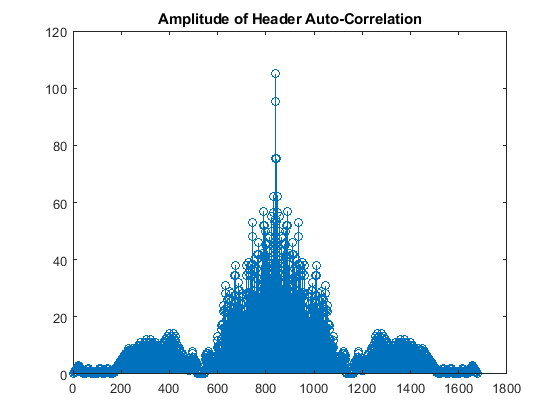

stem(abs(hder_auto_corr))
title('Amplitude of Header Auto-Correlation')

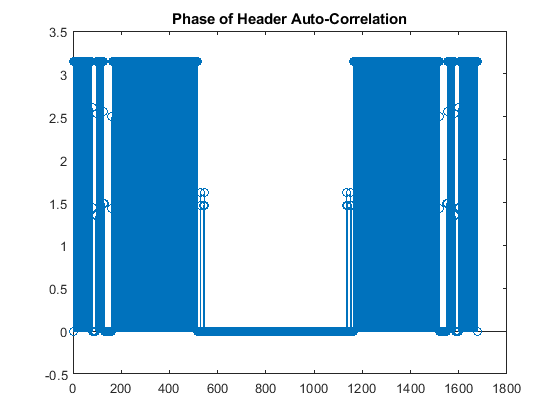

stem(unwrap(angle(hder_auto_corr)))
title('Phase of Header Auto-Correlation')


[~, idx] = max(abs(hder_auto_corr))

idx = 840

angle(hder_auto_corr(idx))*(180/pi)

ans = -4.4105e-15


corr_with_rx_smpl_noise = conv(kernel, rx_smpl_noise)

corr_with_rx_smpl_noise =   -0.0231 + 0.0071i  -0.0787 - 0.0013i  -0.1460 - 0.0255i  -0.2808 - 0.1105i  -0.4166 - 0.2554i  -0.5352 - 0.4414i  -0.6520 - 0.6016i  -0.6626 - 0.7039i  -0.6355 - 0.6804i  -0.6011 - 0.5732i  -0.6146 - 0.5086i  -0.7306 - 0.4752i  -0.9577 - 0.6063i  -1.2034 - 0.8396i  -1.3596 - 1.0078i  -1.4146 - 1.1316i  -1.2608 - 1.0633i  -1.0724 - 0.8736i  -0.9785 - 0.7545i  -1.0143 - 0.6695i  -1.3464 - 0.8667i  -1.7499 - 1.1530i  -2.1019 - 1.3589i  -2.2623 - 1.5520i  -2.0060 - 1.3794i  -1.5985 - 1.0630i  -1.1680 - 0.8563i  -0.8509 - 0.5039i  -1.0013 - 0.5181i  -1.3135 - 0.6538i  -1.6644 - 0.6698i  -1.9517 - 0.8504i  -1.7424 - 0.7285i  -1.3221 - 0.5502i  -0.7417 - 0.4806i  -0.2540 - 0.2873i  -0.2002 - 0.3040i  -0.4021 - 0.3400i  -0.8187 - 0.2878i  -1.1206 - 0.4093i  -1.0848 - 0.3360i  -0.8074 - 0.2258i  -0.3488 - 0.1572i   0.0237 + 0.0525i   0.1108 + 0.2106i  -0.0056 + 0.2847i  -0.2079 + 0.3397i  -0.4288 + 0.3207i  -0.5087 + 0.1901i  -0.4525 + 0.0306i


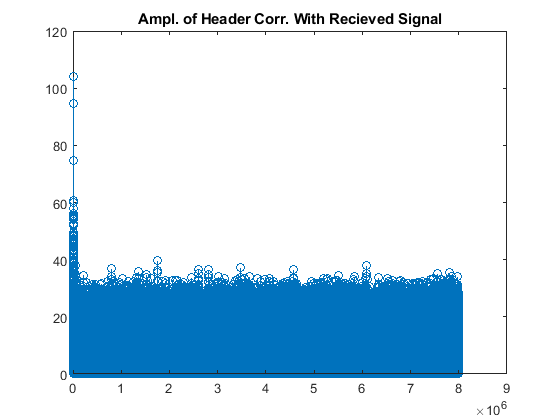

stem(abs(corr_with_rx_smpl_noise))
title('Ampl. of Header Corr. With Recieved Signal')

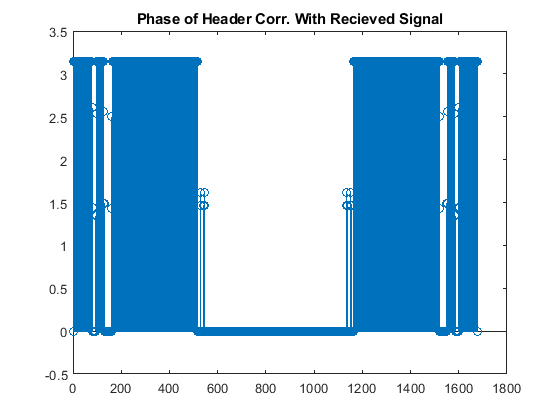

stem(unwrap(angle(hder_auto_corr)))
title('Phase of Header Corr. With Recieved Signal')


[~, idx] = max(abs(corr_with_rx_smpl_noise))

idx = 840

angle(corr_with_rx_smpl_noise(idx))*(180/pi)

ans = 30.5038